### 初始化参数

clc;clear;
fc = 3e3;           %中心频率为3kHz
fs = 24e3;
c = 1500;

### CW信号

T_CW =  0.005;
t_CW = 0:1/fs:T_CW-1/fs;
pulse_CW = cos(2*pi*fc*t_CW);
% N = length(pulse_CW);
% window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

%pulse_CW = pulse_CW.* window;
N = length(pulse_CW);
CW = [pulse_CW zeros(1,4*N)];

#### 频谱

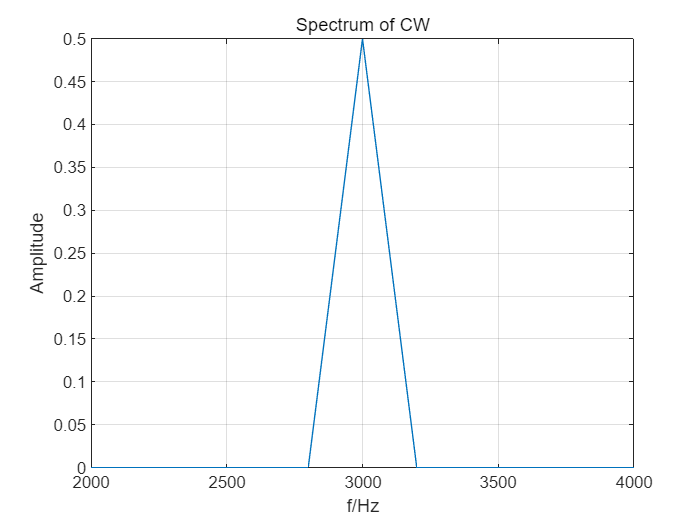

N_fft = length(pulse_CW);
CW_f = fftshift(fft(pulse_CW,N_fft))./N_fft;
freq = -fs/2:fs/N_fft:fs/2-fs/N_fft;


figure
plot(freq,abs(CW_f));
title('Spectrum of CW');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

#### 计算有效相关带宽和有效相关时宽

%计算有效相关时宽
Tc = cal_TSP(pulse_CW,fs);

% 计算有效相关带带宽
FSP = cal_FSP(CW_f,N_fft,fs);

fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 0.003333 s
计算有效相关带宽: 200.000000 Hz


### 模糊函数分析

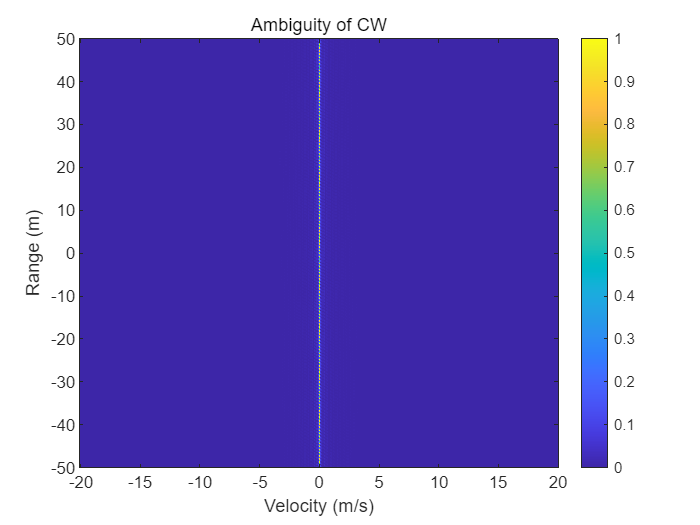

fs_ambiguity = 7e3;
T = 6;            %脉冲长度6s
num_pulse = 1;     %脉冲个数500
t = 0:1/fs_ambiguity:T-1/fs_ambiguity;
pulse_CW = cos(2*pi*fc*t);

[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_CW, pulse_CW, fs_ambiguity, 1500, 20);

    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, Waf./max(max(Waf)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');ylim([-50,50]);
title('Ambiguity of CW');
colorbar;

计算Q函数

保存为wav文件


filename = 'CW.wav';
audiowrite(filename, CW, fs);
Time = num2str(length(CW)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CW.wav 共0.025s


### M序列


T = 2;            %脉冲长度
t = 0:1/fs:T-1/fs;

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M_array = m_seq(gen_435, init_state);
M_array = M_array*2-1;   %0->-1
%M_array = M_array(1:200);  %前200个

t1 = 0:1/fs:T/length(M_array)-1/fs;%每个符号的时间尺度
fc = 3e3;
func = cos(2*pi*fc*t1);
N = length(func);
%window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
%func = func.*window ;

 
pulse = [];
for i = 1:length(M_array)
    pulse = [ pulse M_array(i)*func];
end
M_seq = [pulse zeros(1,4*length(pulse))  ];


#### 频谱

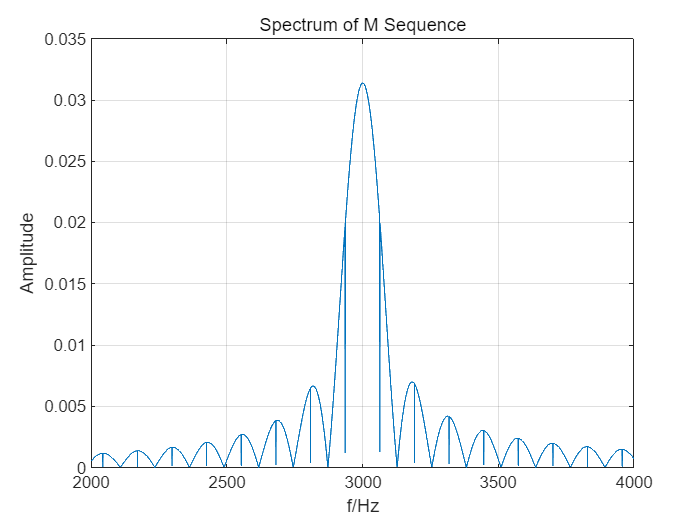

N_fft = length(pulse);
pulse_M_f = fftshift(fft(pulse,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_M_f));
title('Spectrum of M Sequence');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

#### 计算有效相关带宽和有效相关时宽

%计算有效相关时宽
Tc = cal_TSP(pulse,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_M_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 1.331667 s
计算有效相关带宽: 190.350802 Hz


#### 时频谱

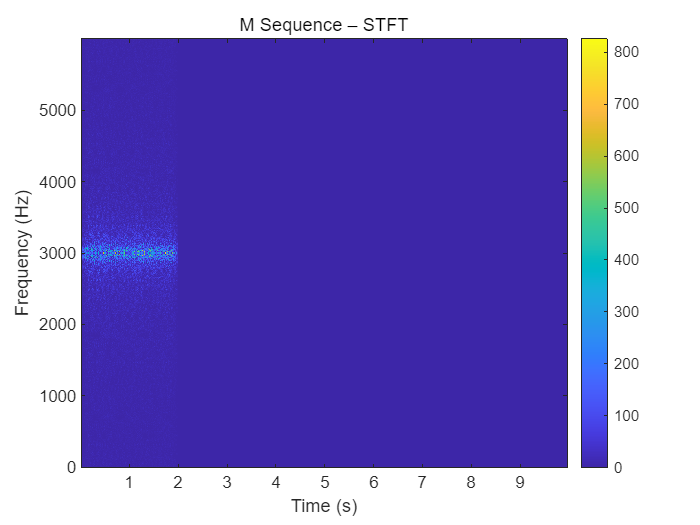

decim = 4;
res_M_seq  = M_seq(1:4:end) ;

Nx   = numel(res_M_seq);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh


[tfr_M_seq,~,~] =tfrwv(res_M_seq.', t_idx, Nfft, 0);

fs_res = fs/decim; % 新采样率
tfr_M_seq_shifted = fftshift(tfr_M_seq, 1); % 沿频率轴(第1维)进行fftshift
f_vec_centered = (-Nfft/2:Nfft/2-1)/Nfft*fs_res; % 双边频率向量，以0为中心
t_sec = (t_idx - 1) / fs_res;
f_vec = (0:Nfft-1)/Nfft*fs_res;
figure;
imagesc(t_sec, f_vec, abs(tfr_M_seq_shifted));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('M Sequence – STFT');
colorbar;

保存为wav

total_sample = 30*fs-length(pulse);
signal = [pulse,zeros(1,total_sample)];

filename = 'wav_files/Mseq_3kHz_2s_200Hz.wav';
audiowrite(filename, signal, fs);
Time = num2str(length(signal)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：wav_files/Mseq_3kHz_2s_200Hz.wav 共30s


#### 分集处理

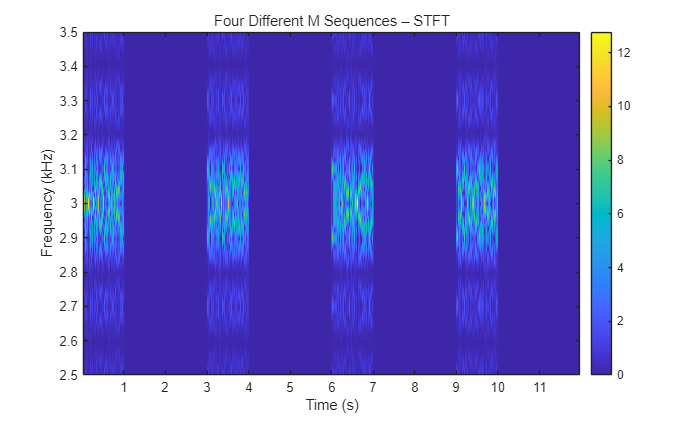

T = 1;            %脉冲长度
t = 0:1/fs:T-1/fs;

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M1 = m_seq(gen_435, init_state);

gen_453 = [1 0 0 1 0 1 0 1 1];
M2 = m_seq(gen_453, init_state);

gen_537 = [1 0 1 0 1 1 1 1 1];
M3 = m_seq(gen_537, init_state);

gen_543 = 	[1 0 1 1 0 0 0 1 1];
M4 = m_seq(gen_543, init_state);

M1 = M1*2-1;M2 = M2*2-1;M3 = M3*2-1;M4 = M4*2-1;
M1 = M1(1:200);M2 = M2(1:200);M3 = M3(1:200);M4 = M4(1:200);

t1 = 0:1/fs:T/length(M1)-1/fs;%每个符号的时间尺度
func = cos(2*pi*fc*t1);
N = length(func);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭
func = func.*window;

pulse_M1 = [];pulse_M2 = [];pulse_M3 = [];pulse_M4 = [];
for i = 1:length(M1)
    pulse_M1 = [ pulse_M1 M1(i)*func];
    pulse_M2 = [ pulse_M2 M2(i)*func];
    pulse_M3 = [ pulse_M3 M3(i)*func];
    pulse_M4 = [ pulse_M4 M4(i)*func];
end
pulse_M1 = [pulse_M1 zeros(1,2*length(pulse_M1))];%设置占空比
pulse_M2 = [pulse_M2 zeros(1,2*length(pulse_M2))];
pulse_M3 = [pulse_M3 zeros(1,2*length(pulse_M3))];
pulse_M4 = [pulse_M4 zeros(1,2*length(pulse_M4))];
pulse_M = [pulse_M1 pulse_M2 pulse_M3 pulse_M4];


decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz
res_pulse_M    = pulse_M   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_pulse_M);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_multiM,~,~] = tfrstft(res_pulse_M.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_multiM));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2.5,3.5]);
title('Four Different M Sequences – STFT');
colorbar;

filename = 'wav_files/CDMA_M.wav';
audiowrite(filename, pulse_M, fs);
Time = num2str(length(pulse_M)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_M.wav 共12s


### Costas序列

T = 2;            %脉冲长度
t = 0:1/fs:T-1/fs;

Costas_array = [1 2 4 8 16 13 7 14 9 18 17 15 11 3 6 12 5 10];%18个符号
Costas_array = Costas_array +ones(1,length(Costas_array));
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

N = length(t1);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1).*window ];
end

#### 频谱

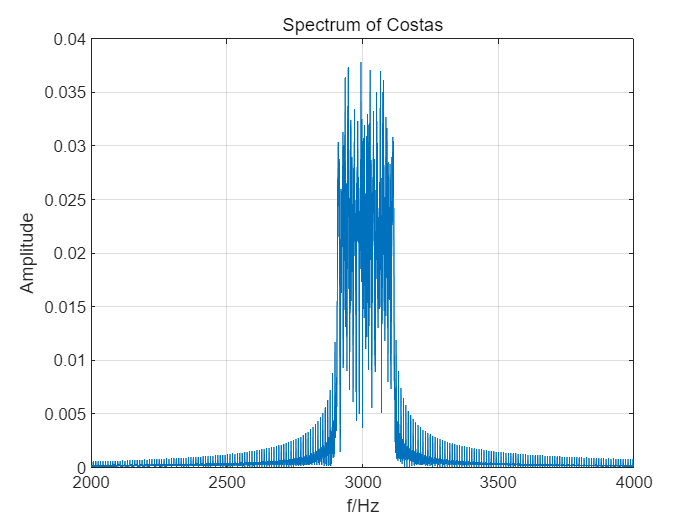

N_fft = length(pulse_costas);
pulse_costas_f = fftshift(fft(pulse_costas,N_fft))./N_fft;
freq = (-fs/2:fs/N_fft:fs/2-fs/N_fft);

figure
plot(freq,abs(pulse_costas_f));
title('Spectrum of Costas');
xlim([2000,4000]);grid on;xlabel('f/Hz');ylabel('Amplitude');

计算有效相关带宽和有效相关时宽


%计算有效相关时宽
Tc = cal_TSP(pulse_costas,fs);

% 计算有效相关带带宽
FSP = cal_FSP(pulse_costas_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 1.322748 s
计算有效相关带宽: 171.106885 Hz


decim = 4;
Costas = [pulse_costas zeros(1,4*length(pulse_costas))];
res_Costas = Costas(1:decim:end);

[tfr_Costas,~,~] = tfrstft(res_Costas.', t_idx, Nfft, win);

函数或变量 't_idx' 无法识别。

figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_Costas));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2,4]);
title('Costas – STFT');
colorbar;

保存为wav

total_sample = 30*fs-length(pulse_costas);
signal = [pulse_costas,zeros(1,total_sample)];


filename = 'wav_files/Costas_3kHz_2s_170Hz.wav';
audiowrite(filename, signal, fs);
Time = num2str(length(signal)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：wav_files/Costas_3kHz_2s_170Hz.wav 共30s


#### 分集处理

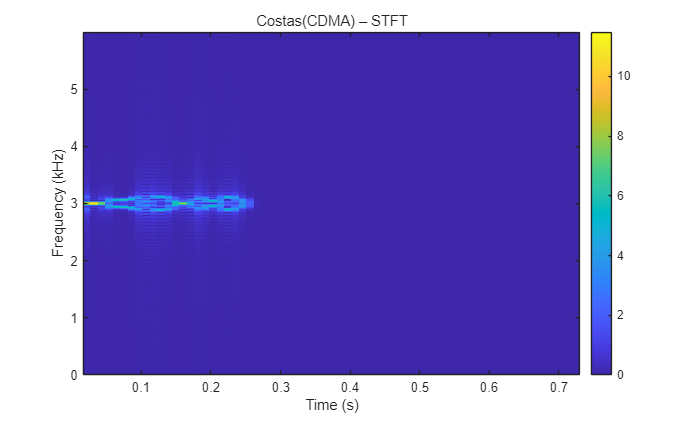

T = 0.25;            %脉冲长度
t = 0:1/fs:T-1/fs;
Costas_array = [2 8 9 12 4 14 10 15 13 7 6 3 11 1 5];%15个符号
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

N = length(t1);
window = kaiser(N, 0.8)';%β 越大 → 滚降越陡峭

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1).*window ];

end
Multi_Costas = [pulse_costas zeros(1,2*length(pulse_costas))];



decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz

res_Multi_Costas    = Multi_Costas   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_Multi_Costas);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_res_Multi_Costas,f_idx,~] = tfrstft(res_Multi_Costas.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_res_Multi_Costas));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Costas(CDMA) – STFT');
colorbar;

保存wav

filename = 'wav_files/CDMA_Costas.wav';
audiowrite(filename, Multi_Costas, fs);
Time = num2str(length(Multi_Costas)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_Costas.wav 共5s


### HFM信号

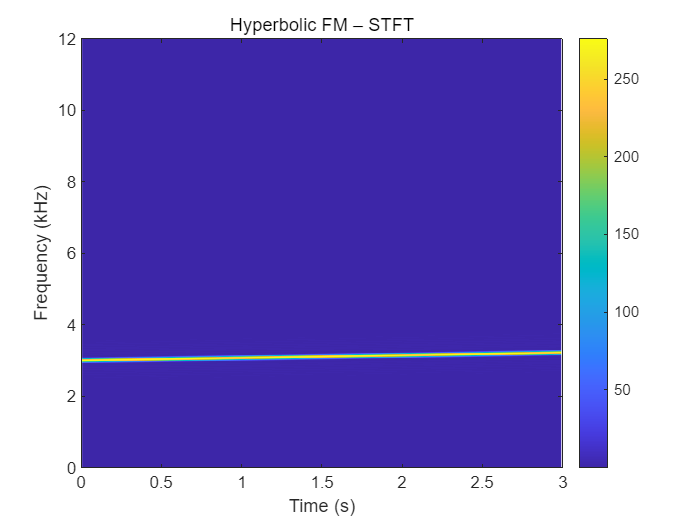

%% 用户参数
fs   = 24e3;      % 采样率
T    = 3;         % 脉冲时长
fmin = 2.9e3;     % 起始频率
fmax = 3.1e3;     % 终止频率
A    = 1;         % 振幅

%% 生成 HFM
[t, s] = hfm_waveform(fs, T, fmin, fmax, A);



%% STFT
wlen   = 512;
nover  = wlen/2;
nfft   = 2048;
[STFT,F,Tstft] = spectrogram(s,wlen,nover,nfft,fs,'yaxis');

%% 绘图
figure;
imagesc(Tstft, F/1e3, abs(STFT));
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Hyperbolic FM – STFT');
axis([0,3,0,12]);
colorbar;

#### 计算有效相关带宽和时宽

%计算有效相关时宽
Tc = cal_TSP(s,fs);
N_fft = length(s);
s_f = fftshift(fft(s,length(s)));
% 计算有效相关带带宽
FSP = cal_FSP(s_f,N_fft,fs);
fprintf('计算有效相关时宽: %.6f s\n计算有效相关带宽: %.6f Hz\n', Tc,FSP);

计算有效相关时宽: 3.000000 s
计算有效相关带宽: 214.745127 Hz


保存为wav


total_sample = 30*fs-length(s);
signal = [s.',zeros(1,total_sample)];


filename = 'wav_files/HFM_3kHz_3s_200Hz.wav';
audiowrite(filename, real(signal), fs);
Time = num2str(length(signal)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：wav_files/HFM_3kHz_3s_200Hz.wav 共30s


#### 分集处理

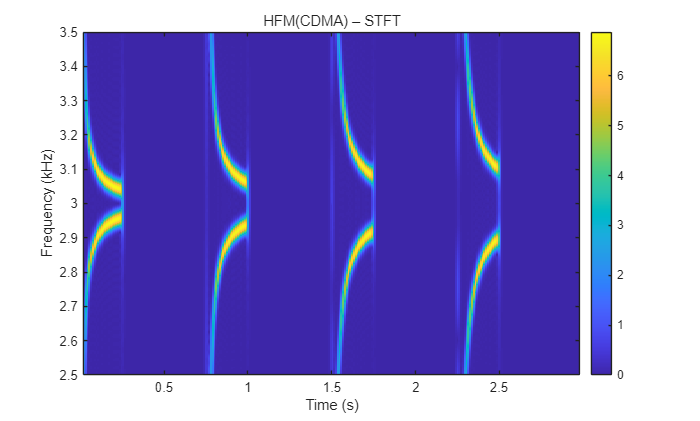


t_hfm = 0.5/fs : 1/fs : T-0.5/fs;
k1 = 10;
k2 = 15;
k3 = 20;
k4 = 25;
pulse1 = cos(2*pi*(fc*t_hfm+k1*log(t_hfm)));  %调频参数K=1
pulse2 = cos(2*pi*(fc*t_hfm+k2*log(t_hfm)));  %调频参数K=2
pulse3 = cos(2*pi*(fc*t_hfm+k3*log(t_hfm)));  %调频参数K=3
pulse4 = cos(2*pi*(fc*t_hfm+k4*log(t_hfm)));  %调频参数K=4

pulse1 = [pulse1 zeros(1,2*length(pulse1))];
pulse2 = [pulse2 zeros(1,2*length(pulse2))];
pulse3 = [pulse3 zeros(1,2*length(pulse3))];
pulse4 = [pulse4 zeros(1,2*length(pulse4))];

Multi_HFM = [pulse1 pulse2 pulse3 pulse4];


decim   = 24;           % <= 24 才安全
fs_res  = fs/decim;     % 新采样率 ≥ 6 kHz


res_Multi_HFM    = Multi_HFM   (1:decim:end);

%% 2. STFT（以 tfrstft 为例）
Nx   = numel(res_Multi_HFM);
hop  = 64;                     % 帧移
Nfft = 2048;                   % 2^k
win  = hamming(257);

Lh   = (length(win)-1)/2;          % 半窗长
t_idx = (Lh+1):hop:(Nx-Lh);        % 跳过左边 Lh 样本，右边也留 Lh
[tfr_res_Multi_HFM,f_idx,~] = tfrstft(res_Multi_HFM.', t_idx, Nfft, win);

% 真实频率向量（Hz）：
f_vec = (0:Nfft-1)/Nfft*fs_res;

% 真实时间向量（s）：
%t_sec = -t_i/fs_res;
t_sec = (t_idx - 1) / fs_res;    % ← 自己算，而不是用 t_i
%% 3. 画图
figure;
imagesc(t_sec, f_vec/1e3, abs(tfr_res_Multi_HFM));   % /1e3 -> kHz
axis xy tight;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
ylim([2.5,3.5]);
title('HFM(CDMA) – STFT');
colorbar;

filename = 'wav_files/CDMA_HFM.wav';
audiowrite(filename, Multi_HFM, fs);
Time = num2str(length(Multi_HFM)*(1/fs));
disp(['音频文件已保存为：', filename,' 共',Time,'s']);

音频文件已保存为：CDMA_HFM.wav 共1.25s


#### M序列

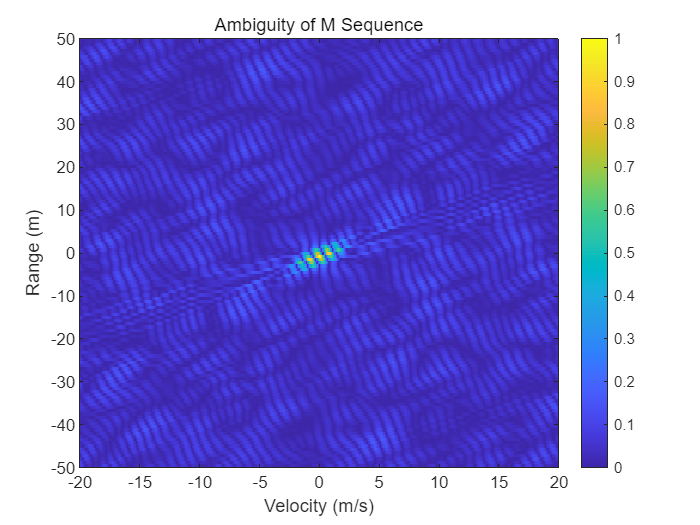

gen_435 = [1 0 0 0 1 1 1 0 1];  % x^8 + x^4 + x^3 + x^2 + 1
init_state = [1 0 1 0 1 0 1 0];  % 8位初始状态，必须非零
M1 = m_seq(gen_435, init_state);

gen_453 = [1 0 0 1 0 1 0 1 1];
M2 = m_seq(gen_453, init_state);

M1 = 2*M1-1;M2 = 2*M2-1;
M1 = M1(1:200);M2 = M2(1:200);

T=0.635;
fs = 1000;
t1 = 0:1/fs:T/length(M1)-1/fs;%每个符号的时间尺度

fc = 500;
func = cos(2*pi*fc*t1);

pulse_M1 = [];pulse_M2 = [];
for i = 1:length(M1)
    pulse_M1 = [ pulse_M1 M1(i)*func];
    pulse_M2 = [ pulse_M2 M2(i)*func];
end


c=1500;
vel_resolution = 0.01;
max_velocity = 20;


[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_M1, pulse_M1, fs, c, max_velocity);
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, Waf./max(max(Waf)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Ambiguity of M Sequence');
ylim([-50,50]);
xlim([-20,20]);
colorbar;

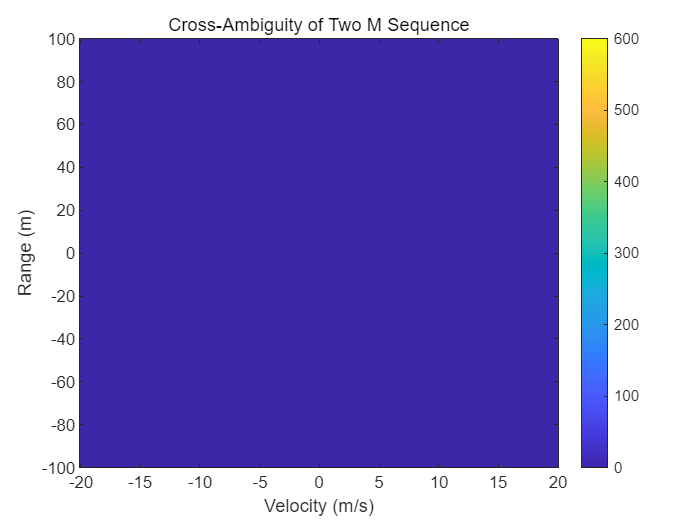


% 获取第一张图的 Waf 的最大值和最小值
cmin = min(Waf(:));
cmax = max(Waf(:));

[Waf, vel_axis,range_axis] = wideband_ambiguity(pulse_M1, pulse_M2, fs, c, max_velocity);
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, Waf./(max(max(Waf))+eps));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
title('Cross-Ambiguity of Two M Sequence');
ylim([-100,100]);
colorbar;
% 设置第二张图的 colorbar 范围与第一张图一致
clim([cmin, cmax]);

#### Costas序列

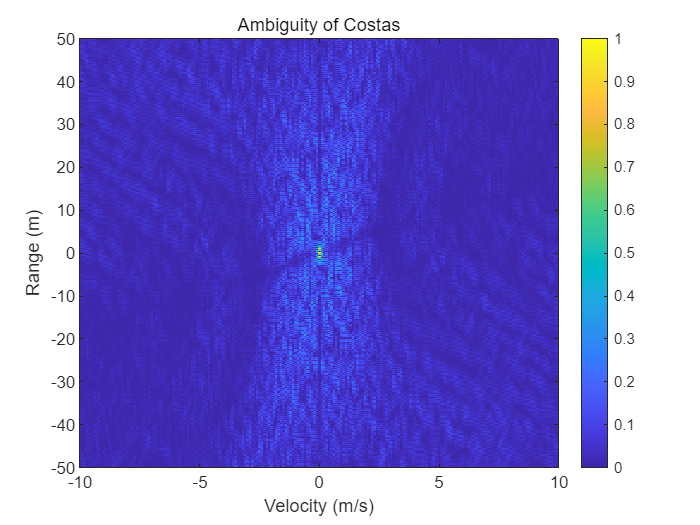

Costas_array = [2 8 9 12 4 14 10 15 13 7 6 3 11 1 5];%15个符号

T = 1.4;            %脉冲长度
t1 = 0:1/fs:T/length(Costas_array)-1/fs;   %每个符号的时间尺度
fmin = 2.9e3;   fmax = 3.1e3;
delta_freq = (fmax-fmin)/(length(Costas_array)-1);

pulse_costas = [];
for i=1:length(Costas_array)
    pulse_costas = [ pulse_costas  cos(2*pi*( fmin + (Costas_array(i)-1) * delta_freq) * t1) ];

end
max_velocity = 20;

[RDM, vel_axis, range_axis] = wideband_ambiguity(pulse_costas, pulse_costas, fs, c, max_velocity);
    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, RDM./max(max(RDM)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
ylim([-50,50]);
xlim([-10,10])
title('Ambiguity of Costas');
colorbar;

#### HFM信号

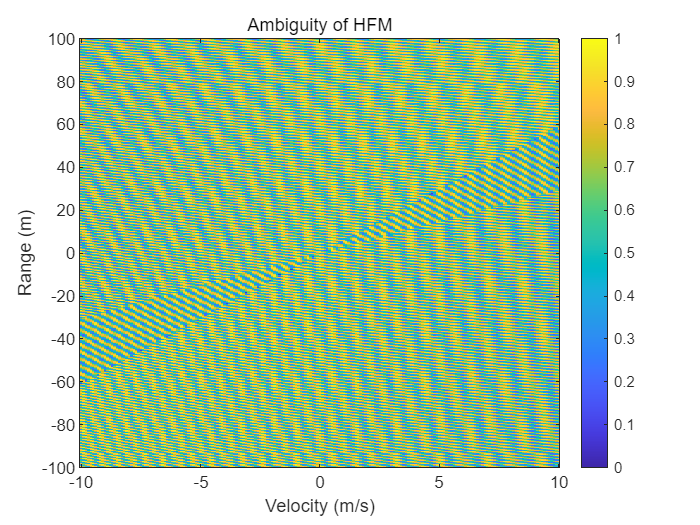

fs = 4e3;
t_hfm = 0.5/fs : 1/fs : T-0.5/fs;
T    = 3;         % 脉冲时长
fmin = 1.5e3;     % 起始频率
fmax = 1.7e3;     % 终止频率
A    = 1;         % 振幅


%% 生成 HFM
[t_hfm, pulse_HFM] = hfm_waveform(fs, T, fmin, fmax, A);

max_velocity = 10;
[RDM, vel_axis, range_axis] = wideband_ambiguity(pulse_HFM, pulse_HFM, fs, 1500, max_velocity);
    
% 绘制距离-多普勒图
figure;
imagesc(vel_axis, range_axis, RDM./max(max(RDM)));
axis xy tight;
xlabel('Velocity (m/s)');
ylabel('Range (m)');
ylim([-100,100]);
title('Ambiguity of HFM');
colorbar;

混响信号仿真

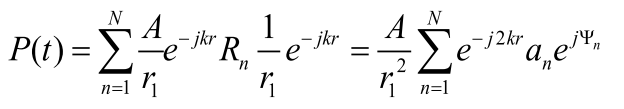

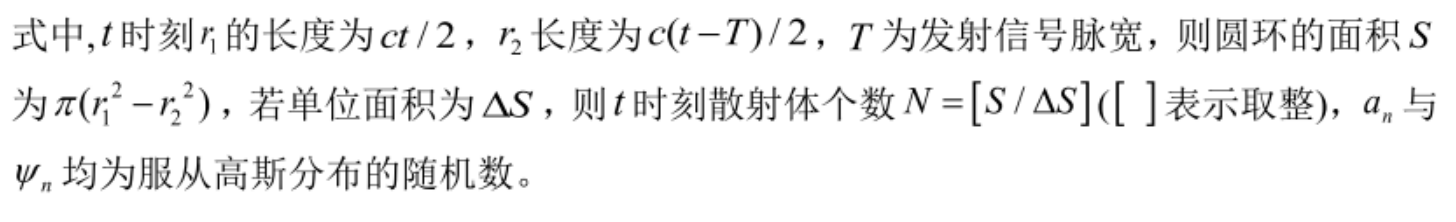

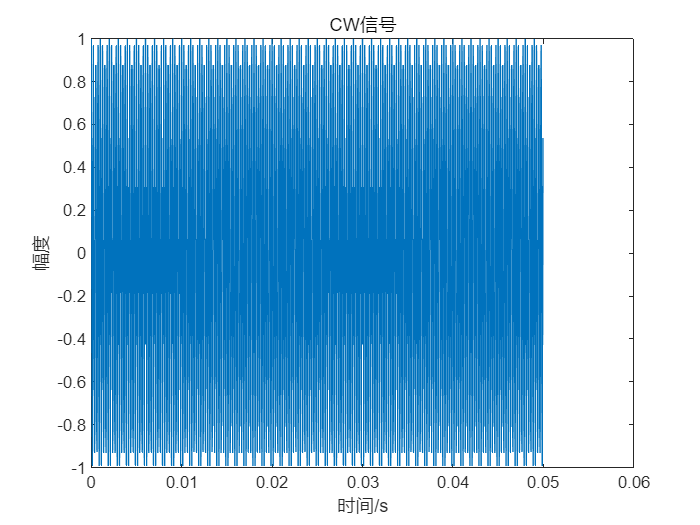

H=100;              %海水深度
D=50;               %合置声纳深度
c=1500;             %声速
azm=pi/6;          %水平方位角
u=-27;              %垂直散射系数
v=20;              %声纳运动速度
fs=25000;           %采样频率
f0=4000;            %中心频率
T=0.001;          %仿真步长
rou=0.5; % 0.85;    %散射体密度

startt=0.08;        %混响起始时间
endt=0.5;          %混响起始时间
t=0:1/fs:endt-1/fs;
Nt=length(t);
Rb1=zeros(size(t));

R1=zeros(size(t));

t1=0.05;

ts=0:1/fs:t1-1/fs;
s1=exp(1i*2.*pi.*f0.*ts);                 %CW信号

Ns=length(ts);
% 信号时域
figure(1);
plot(ts,real(s1));
axis([0 0.06 -1 1]);    %axis([xmin xmax ymin ymax])
xlabel('时间/s');
ylabel('幅度');
title('CW信号');

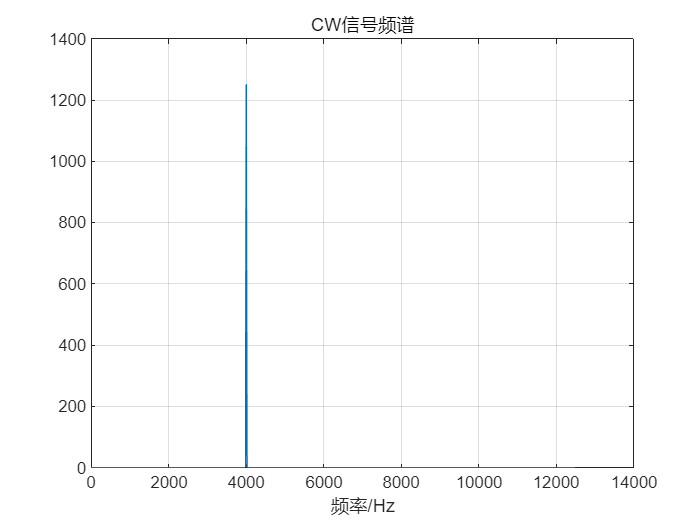


%信号频谱
X1=abs(fft(s1));

figure(2);

f=fs*(0:Ns/2)/Ns;
plot(f,X1(1:Ns/2+1));
xlabel('频率/Hz');
title('CW信号频谱')
grid on;%添加网格

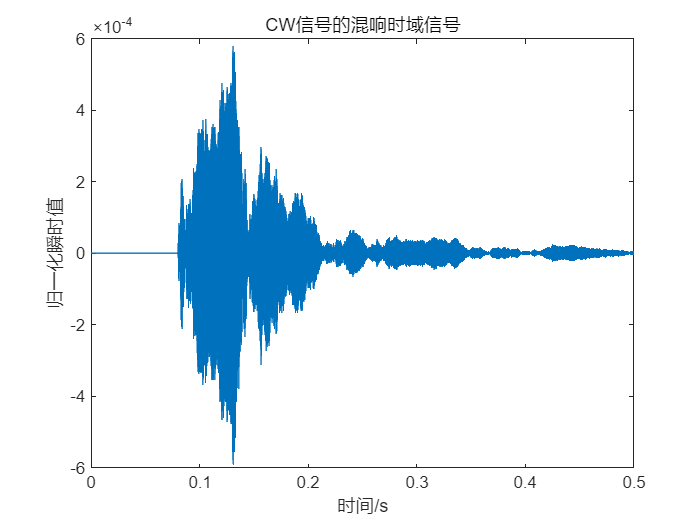


m=20; %m次运算取平均
for i=1:m
    for tr=startt:T:endt
        r1=tr*c/2;
        r2=(tr+T)*c/2;
        As=(r2^2-r1^2)*azm/2;
        Na=poissrnd(As*rou,1,1);  %产生均值为面积的按泊松分布的一个数
        r=r1+rand(1,Na)*(r2-r1);
        phi=rand(1,Na)*2*pi;
        alf=-pi/12+pi/6.*rand(1,Na);
        for n=1:Na
                d=r(n);
                %计算多普勒频移
                cosbt=(sqrt((r(n))^2-D^2))/r(n);
                fd1=2*v/c*f0*cos(alf(n))*cosbt;
                s1p=exp(1i*2.*pi.*(f0+fd1).*ts);%多普勒频移相当于对入射波进行了频移

                Nrt=fix(d/c*2*fs);%取整
                Sr=sqrt(10^(u/10))*(H-D)/d;     %散射损失，采用兰伯特（Lambert）定律
                Fr=1/d;                         %传播损失
                h=Sr*Fr^2*exp(1i*phi(n));                
                if Nrt+Ns>Nt
                    Rb1(Nrt+1:Nt)=Rb1(Nrt+1:Nt)+s1p(1:Nt-Nrt).*h;
                else
                    Rb1(Nrt+1:Nrt+Ns)=Rb1(Nrt+1:Nrt+Ns)+s1p.*h;
                end
        end
    end
    R1=R1+Rb1;
end
%混响时域信号
R1=R1/m;
Rr1=real(R1);

figure(3);
plot(t,Rr1);
xlabel('时间/s');
ylabel('归一化瞬时值');
title('CW信号的混响时域信号');

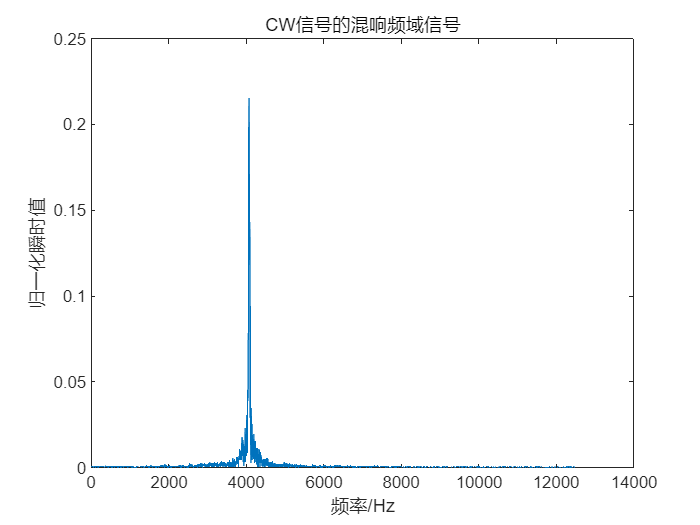


%混响频谱
F1=abs(fft(Rr1));                
figure(4);
f1=fs*(0:Nt/2)/Nt;
plot(f1,F1(1:Nt/2+1));
xlabel('频率/Hz');
ylabel('归一化瞬时值');
title('CW信号的混响频域信号');

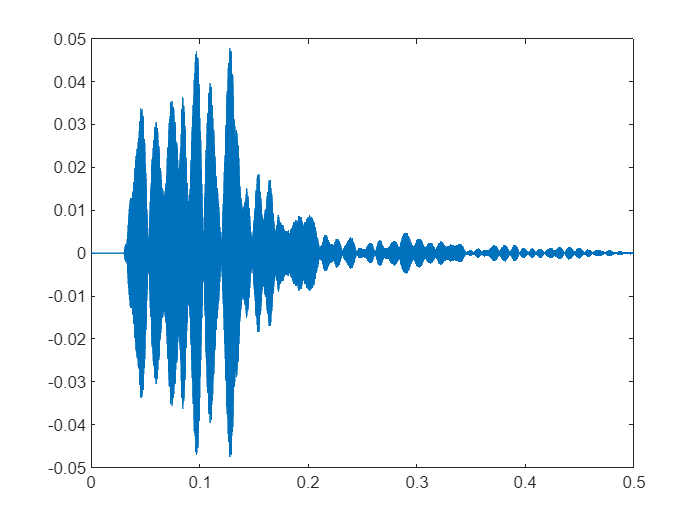



%%%%%%求多普勒%%%%%%%%%%%%%%%%%%%%%%%
tao=0.002;
fai=pi/6;
%%%找底位置%%%%%%%
tc=0:1/fs:endt-1/fs;
cpy=exp(1i*2*pi*f0*tc).*(tc>0 & tc<t1);
CPY=conj(fft(cpy));

R2=fft(R1);
crr=ifft(R2.*CPY);

figure(5)
plot(t,real(crr))


[~,bt]=max(real(crr));


tn=tao*fs;
x1=R1(bt:end-tn);
x2=R1(bt+tn:end);
xout=x1*x2';
fb=abs(angle(xout)/2/pi/tao)

fb = 79.0038

vout=fb*c/2/cos(fai)/f0

vout = 17.1048

宽带模糊函数

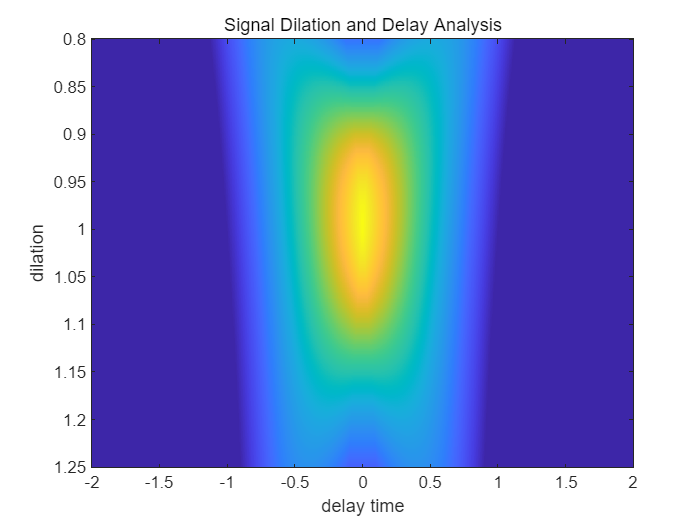




 % wide band ambiguity function
clc
clear all
close all
    %
function plot_wideband_ambiguity(tb, tend, dilation, c, signal)
    % 输入参数说明：
    % tb: 时间起始点
    % tend: 时间结束点
    % dilation: 延迟范围的缩放因子
    % c: 常数（例如速度）
    % signal: 输入信号

    % 计算共轭反转信号
    conj_rev_signal = conj(signal(end:-1:1));
    
    % 时间向量
    time = linspace(tb, tend, length(signal));
    
    % 延迟时间向量
    delay_time = linspace(2 * tb, 2 * tend, 2 * length(signal) - 1);
    
    % 计算τ范围
    tau = linspace(dilation, 1 / dilation, 512);
    
    % 初始化输出矩阵
    out = zeros(length(tau), 2 * length(signal) - 1);
    
    % 循环计算卷积
    for i = 1:length(tau)
        out(i, :) = conv(signal, interp1(time, conj_rev_signal, time * tau(i), 'spline'));
    end
    
    % 绘制结果
    figure(1)
    imagesc(delay_time, tau, abs(out))
    xlabel('delay time');
    ylabel('dilation');
    title('Signal Dilation and Delay Analysis');
end
    % 定义信号
tb = -1;
tend = 1;
dilation = 0.8;
c = 1500;
signal = [zeros(1, 100), exp(1j * 2 * pi * (4 * [0:199]) / 200), zeros(1, 100)];

% 调用函数
plot_wideband_ambiguity(tb, tend, dilation, c, signal);